# Aufgabe 3

Teil1

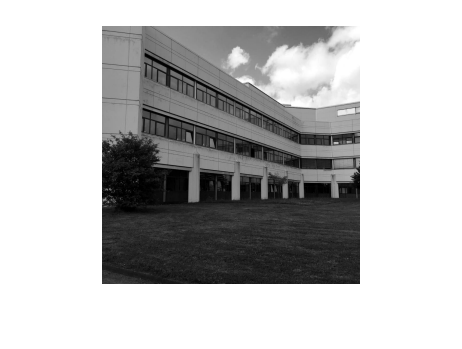

img = imread("FhGebaude.png");
imshow(img)


h1 = [1 1 1; 1 -8 1; 1 1 1];
h2 = 1 / 16 * [1 2 1; 2 4 2; 1 2 1];
h3 = [1 2 1; 0 0 0; -1 -2 -1];

imgD = im2double(img);
h = fspecial('sobel')

h =      1     2     1
     0     0     0
    -1    -2    -1



filteredImg = imfilter(imgD, h, 'conv');
figure, imshow(imgD, [])

...

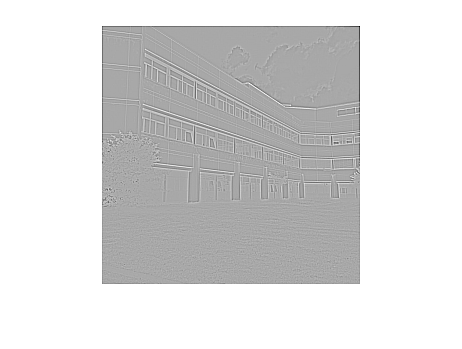

[row, col, ~] = size(imgD);
k = 1;
thickness = 2 * k + 1;
out1 = zeros(row, col, class(imgD));
out2 = zeros(row, col, class(imgD));
out3 = zeros(row, col, class(imgD));

for x = 1 : row
    for y = 1 : col
        roi = zeros(thickness, thickness, class(imgD));
        for r = -k : k 
            for c = -k : k    
                if(y + c < 1 || x + r < 1)
                    roi(r + k + 1, c + k + 1) = 0;
                elseif(y + c > col || x + r > row) 
                    roi(r + k + 1, c + k + 1) = 0;
                else
                    roi(r + k + 1, c + k + 1) = imgD(x + r, y + c);
                end    
            end
        end
        
        out1(x, y) = sum(sum(roi .* h1));
        out2(x, y) = sum(sum(roi .* h2));
        out3(x, y) = sum(sum(roi .* h3));
    end
end

imshow(out1, [])

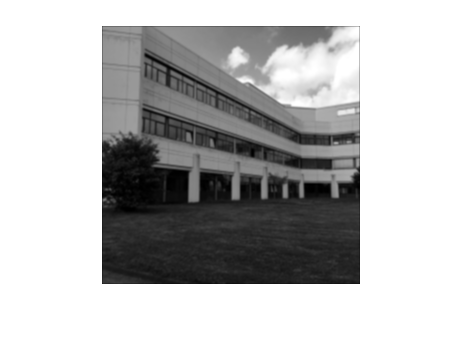

imshow(out2, [])

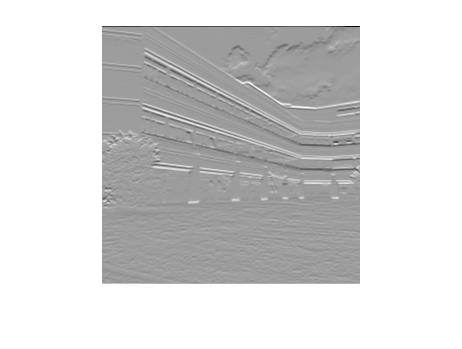

imshow(out3, [])